%Measurment Name
Exercise = "Exercise_2";
Measurement = "Stationary_FRF_Closed_loop_ex_ab";
SampleFreq = "fs_" + 4000 + "_Hz";

Path = "TestMeasurements/"  ...
        + Exercise ...
        + "/" + SampleFreq

Path = "TestMeasurements/Exercise_2/fs_4000_Hz"



test1r = GetData("MyMeasurements/TestMeasurements/MeasurementOrder",1)

test1r = struct with fields:
    Data: [1×1 struct]


test1 = test1r.Data.calculatedData

test1 = struct with fields:
    f: [3001×1 double]
    H: [3001×1 double]
    S: [3001×2 double]
    C: [3001×2 double]


%test1 = GetProcessedData(Path,"3_point",1)
test2 = GetProcessedData(Path,"3_point",2)

test2 = struct with fields:
    f: [1001×1 double]
    H: [1001×1 double]
    S: [1001×2 double]
    C: [1001×2 double]


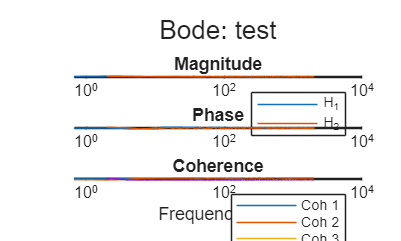

ans =   Figure (19) with properties:

      Number: 19
        Name: ''
       Color: [1 1 1]
    Position: [323 225 560 337.2667]
       Units: 'pixels'

  Show all properties



% d = test1r.Data.signals.d;
% e = test1r.Data.signals.e;
% u = test1r.Data.signals.u;
% noverlap = test1r.Data.settings.noverlap;
% window = test1r.Data.settings.window;
% Fs = test1r.Data.settings.fs;
% nfft = test1r.Data.settings.nfft;
% 
% [f, H, S, C] = threePoint(d,e,u,window,noverlap,nfft,Fs);
% test2 = struct("f",f, "H",H, "S",S, "C",C)                
% test1.C
PlotProcessedData([test1 test2], "test")

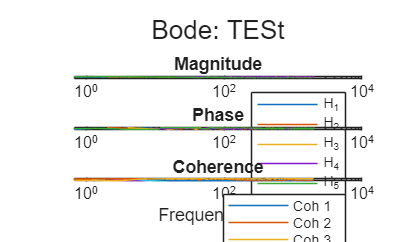

ans =   Figure (20) with properties:

      Number: 20
        Name: ''
       Color: [1 1 1]
    Position: [323 225 560 337.2667]
       Units: 'pixels'

  Show all properties



PlotProcessedData([ ...
    GetProcessedData(Path,"3_point",1) ...
    GetProcessedData(Path,"3_point",2) ...
    GetProcessedData(Path,"3_point",3)...
    GetProcessedData(Path,"3_point",4)...
    test1...
    ], ...
    "TESt")


% 
% function [fig, H_tile, Coh_tile] = PlotProcessedData(data,title)
%     w = length(data);    
%     l = 0;
%     for i = 1:w
%         l = max(l, length(data(i).f));
%         l = max(l, length(data(i).H));
%         l = max(l, length(data(i).C));
%     end
% 
% 
%     %build data vectors
%     F = zeros(l,w);
%     H = zeros(l,w);
%     c_w = 0;
%     for i = 1:w
%         size_C = size(data(i).C);
%         c_w = c_w + size_C(2);
%     end
%     C = zeros(l,c_w);
%     j = 0;
%     for i = 1 : length(data)
%         F(1:length(data(i).f),i) = data(i).f;
%         H(1:length(data(i).H),i) = data(i).H;
%         size_C = size(data(i).C);
%        for k = 1 : size_C(2)
%             j = j+1;
%             C(1:length(data(i).C(:,k)),j) = data(i).C(:,k);
%         end
%     end
% 
%    [fig, H_tile, Coh_tile] = mybode(F,H,C,title);
% 
% end
% 
% function processedData = GetProcessedData(Path, processedType, MeasurementNumber)
%     folder = Path + "/processed_signals/" + processedType + "/MeasurementOrder";
%     found = GetData(folder,MeasurementNumber);
% 
%     if(isempty(found))
%         processedData = [];
%         return;
%     end
%     processedData = found.Data.calculatedData;
% end
% 
% function foundData = GetData(Folder, Number)
%     files = dir(fullfile(Folder, '*_*'));  % only files with underscore
%     files = files(~[files.isdir]);          % remove any folders
% 
%     filePath = "";
%     for k = 1:length(files)
%         nameParts = split(files(k).name, '_'); 
%         if str2double(nameParts{1}) == Number
%             filePath = fullfile(Folder, files(k).name);  % full path to the file
%             break;  % exit loop once found
%         end
%     end
% 
%     if(filePath == "")
%         warning("File #" + Number + " not found!");
%         foundData = [];
%         return;
%     end
%     foundData = load(filePath);
% end